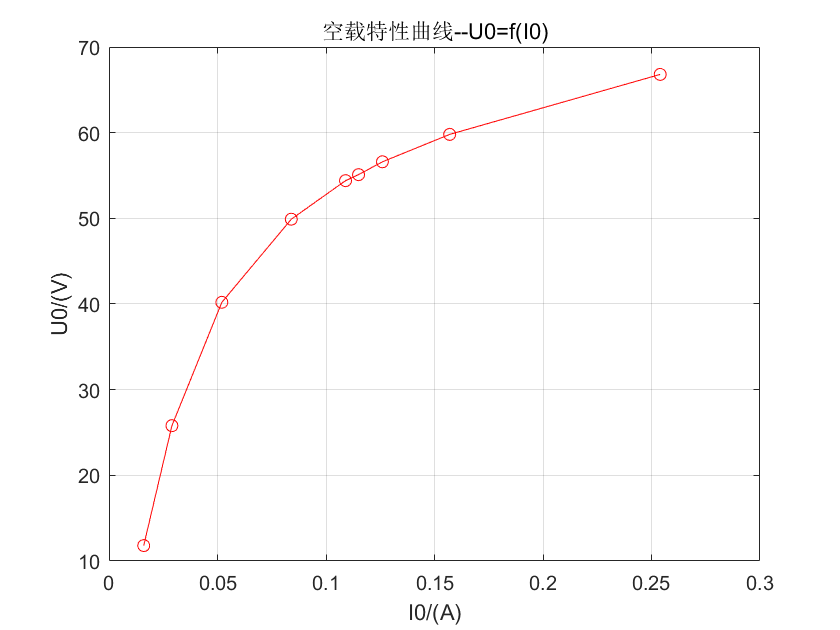

U0 = [66.8 59.8 56.6 55.1 54.4 49.9 40.2 25.8 11.8];
I0 = [0.254 0.157 0.126 0.115 0.109 0.084 0.052 0.029 0.016];
P0 = [2.3 1.9 1.7 1.5 1.5 1.3 0.9 0.5 0.1];
U_AX = [260 233 220 215 212 195 155.4 100.5 48.3];
K = U_AX./U0;
K_mean = mean(K);
cosfai0 = P0./(U0.*I0);
plot(I0,U0,'ro-')
title('空载特性曲线--U0=f(I0)');
xlabel('I0/(A)')
ylabel('U0/(V)')
grid on

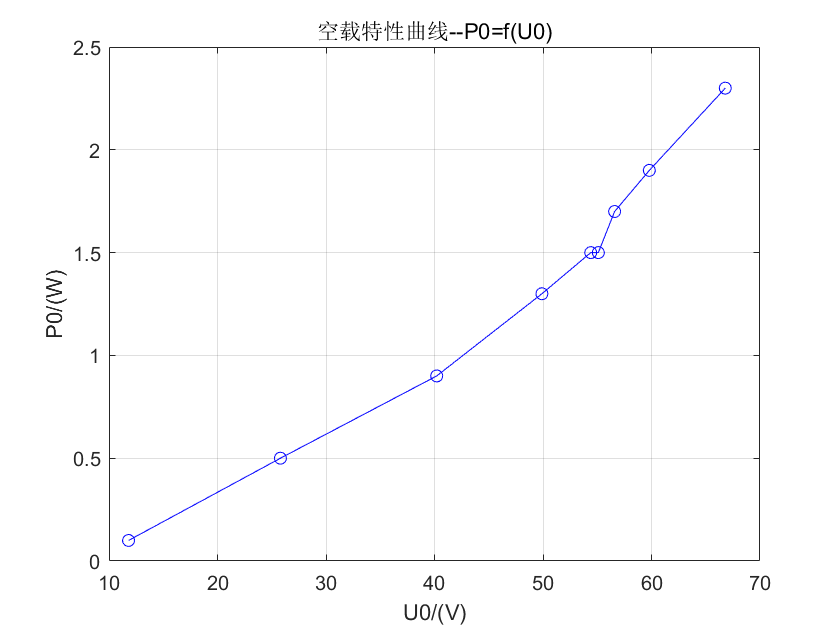


plot(U0,P0,'bo-')
title('空载特性曲线--P0=f(U0)');
xlabel('U0/(V)')
ylabel('P0/(W)')
grid on

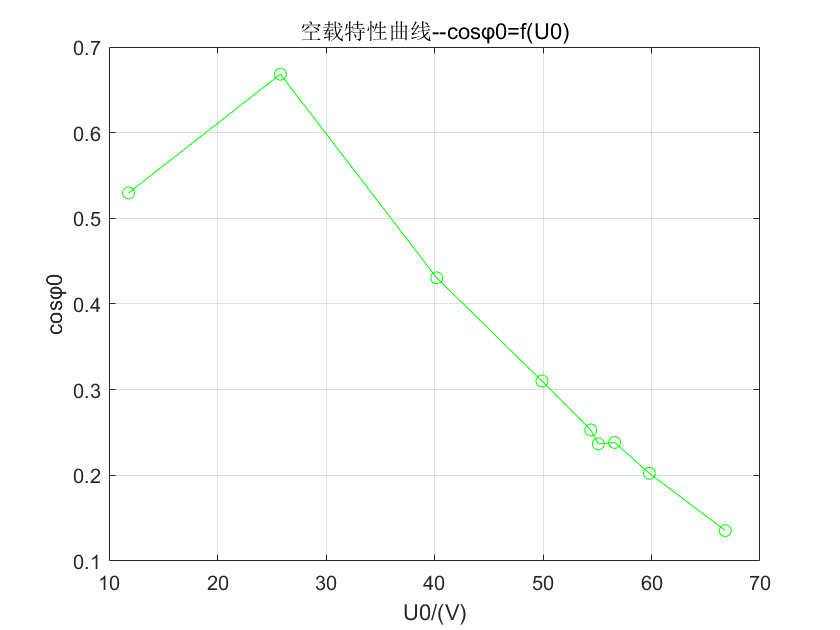


plot(U0,cosfai0,'go-')
title('空载特性曲线--cosφ0=f(U0)');
xlabel('U0/(V)')
ylabel('cosφ0')
grid on


Uk = [31.9 29.5 29 28 24.1 16.9 12.3 5.7];
Ik = [0.385 0.356 0.351 0.338 0.292 0.205 0.15 0.07];
Pk = [5.5 4.7 4.5 4.3 3.1 1.7 0.8 0.1];
cosfaik = Pk./(Uk.*Ik)

cosfaik =     0.4478    0.4475    0.4421    0.4544    0.4405    0.4907    0.4336    0.2506


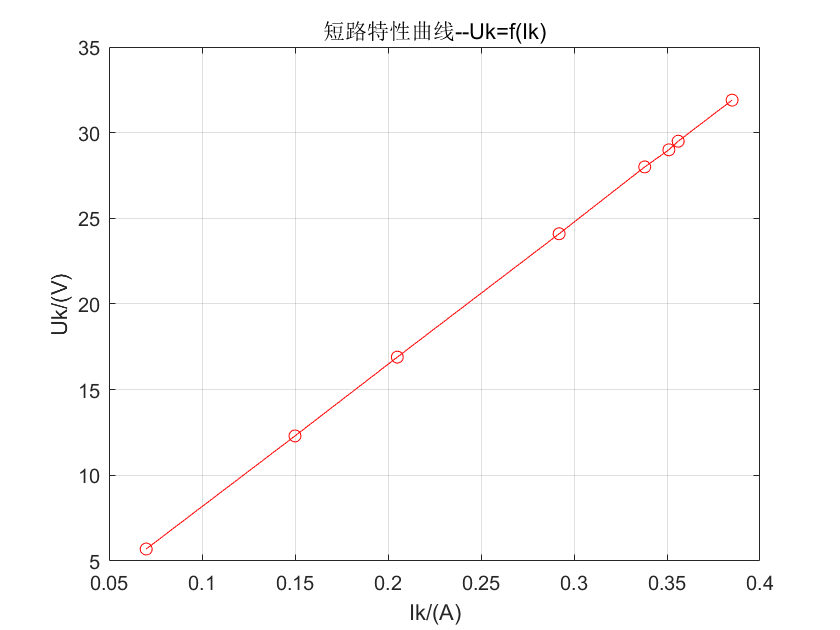

plot(Ik,Uk,'ro-')
title('短路特性曲线--Uk=f(Ik)');
xlabel('Ik/(A)')
ylabel('Uk/(V)')
grid on

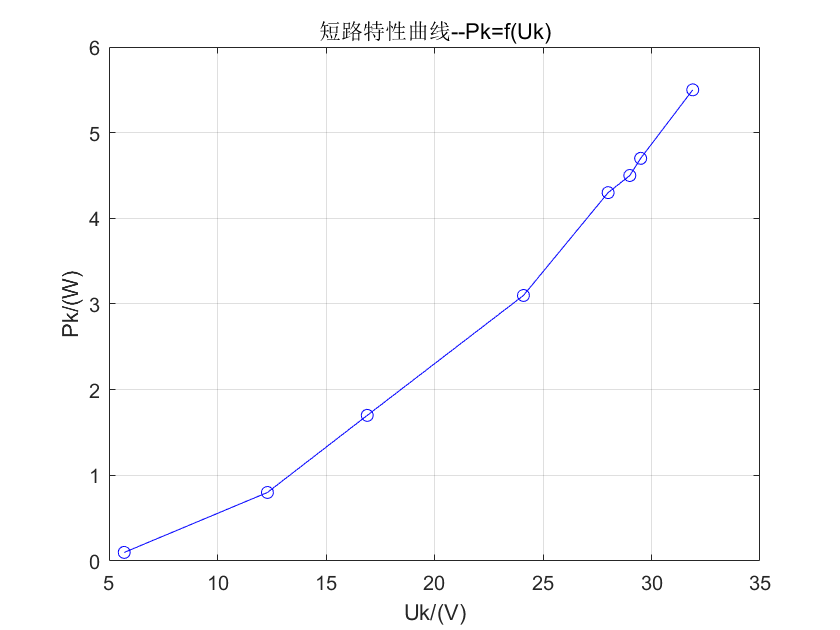


plot(Uk,Pk,'bo-')
title('短路特性曲线--Pk=f(Uk)');
xlabel('Uk/(V)')
ylabel('Pk/(W)')
grid on

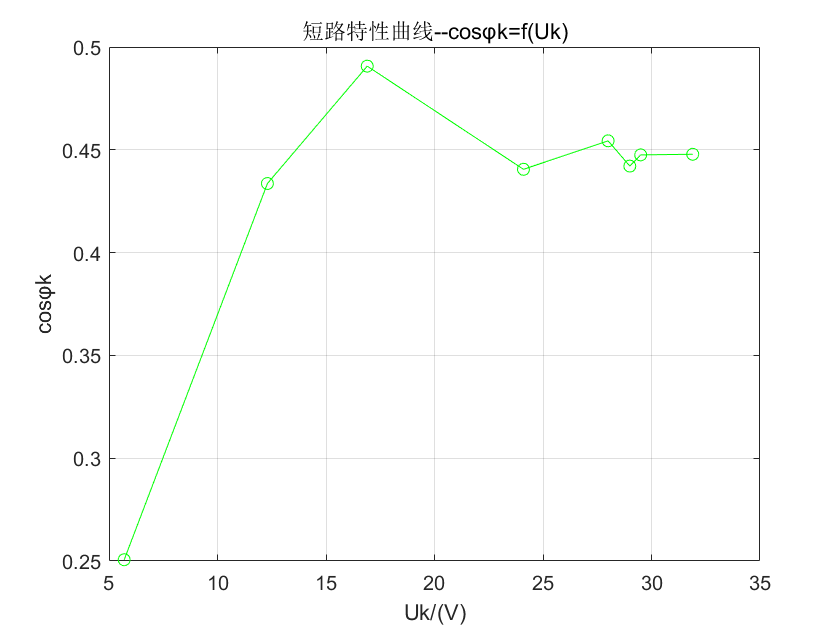


plot(Uk,cosfaik,'go-')
title('短路特性曲线--cosφk=f(Uk)');
xlabel('Uk/(V)')
ylabel('cosφk')
grid on



rm = P0./(I0.*I0);
rm_mean = mean(rm);
zm = U0./I0;
zm_mean = mean(zm);
Xm = sqrt(zm_mean^2-rm_mean^2);
Xm1 = sqrt(zm.^2-rm.^2)

Xm1 =   260.5646  373.0105  436.2571  465.5121  482.8497  564.7549  697.7573  661.8308  625.5544


Xm2 = mean(Xm1)

Xm2 = 507.5657


zk1 = mean(Uk./Ik)

zk1 = 82.4482

rk1 = mean(Pk./(Ik.^2))

rk1 = 35.1411

xk1 = sqrt(zk1^2-rk1^2)

xk1 = 74.5842


zk2 = zk1/(K_mean^2)

zk2 = 5.3787

rk2 = rk1/(K_mean^2)

rk2 = 2.2925

xk2 = xk1/(K_mean^2)

xk2 = 4.8657

UAB = 380;
Uab = 53.0;
UBb = 430.0;
UCc = 430.0;
UBc = 430.0;
Kl = UAB/Uab

Kl = 7.1698

UBb_2 = Uab*(sqrt(Kl^2-(sqrt(3)*Kl))+1)

UBb_2 = 383.9328

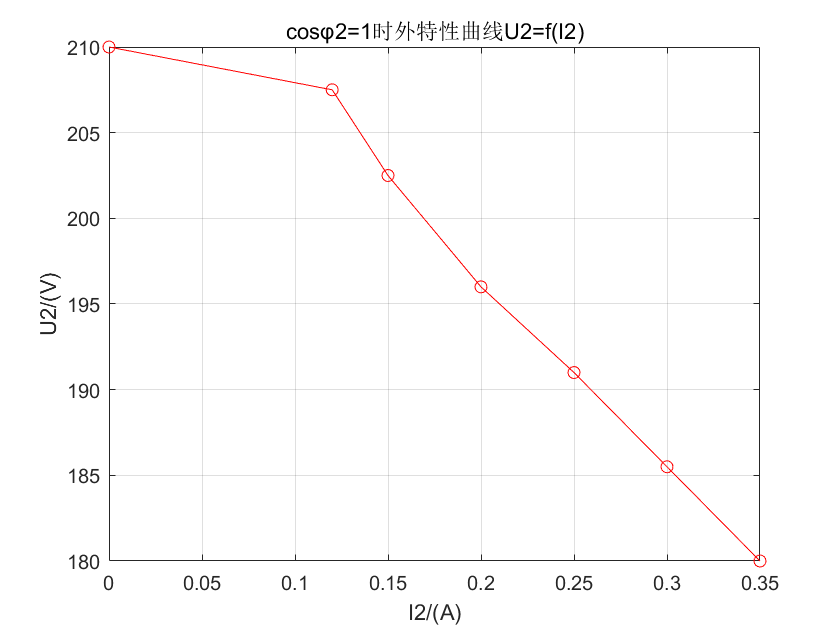

U2_1 = [210 207.5 202.5 196 191 185.5 180];
I2_1 = [0 0.12 0.15 0.2 0.25 0.3 0.35];

U2_2 = [52.3 55.3 54.7 53.8 52.8 52.1 51.8];
I2_2 = [0.12 0.15 0.2 0.25 0.3 0.33 0.35];

plot(I2_1,U2_1,'or-')
title('cosφ2=1时外特性曲线U2=f(I2)')
xlabel('I2/(A)')
ylabel('U2/(V)')
grid on

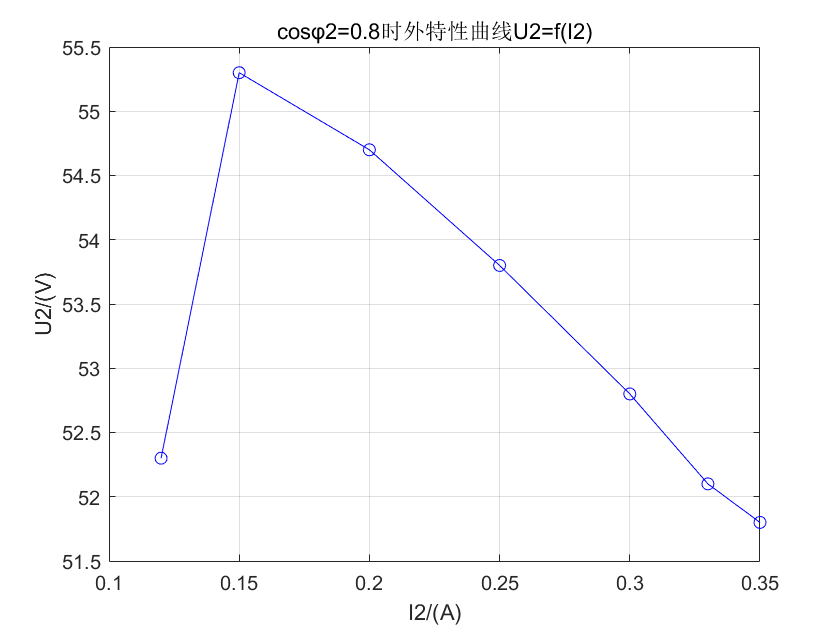


plot(I2_2,U2_2,'ob-')
title('cosφ2=0.8时外特性曲线U2=f(I2)')
xlabel('I2/(A)')
ylabel('U2/(V)')
grid on

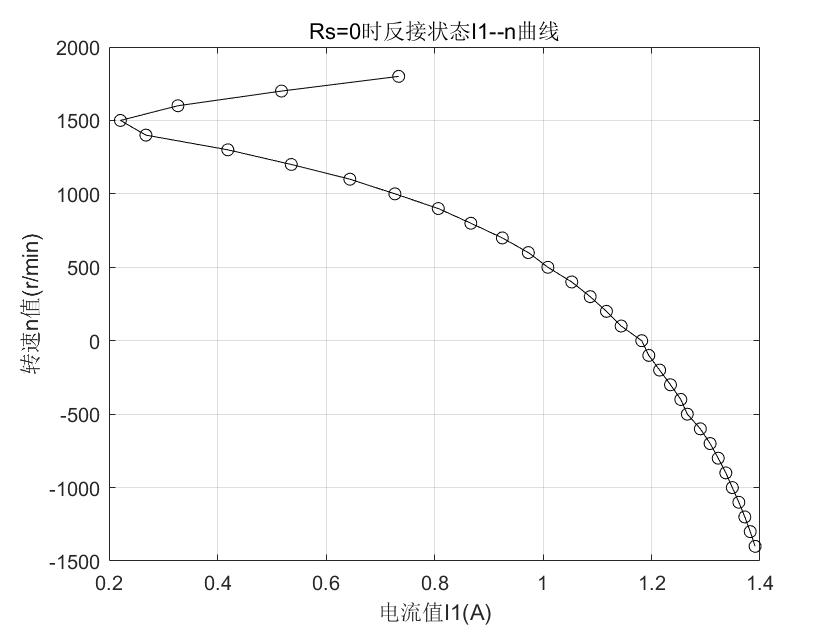

clear
n1 = [1800:-100:-1400] ;
Ua1 = [214 210 202 187 176 158 146 132 121 107 96 82 70 58 45 33 20 7 -5 -17 -29 -42 -55 -68 -78 -92 -104 -117 -129 -141 -154 -167 -179];
Ia1 = [0.94 0.62 0.38 0.14 0 -0.15 -0.23 -0.29 -0.32 -0.34 -0.35 -0.35 -0.35 -0.35 -0.35 -0.35 -0.34 -0.33 -0.53 -0.53 -0.53 -0.53 -0.53 -0.54 -0.54 -0.54 -0.55 -0.55 -0.55 -0.56 -0.56 -0.56 -0.56];
I1 = [0.734 0.518 0.327 0.221 0.268 0.419 0.536 0.644 0.727 0.807 0.867 0.925 0.973 1.009 1.053 1.087 1.117 1.144 1.182 1.195 1.215 1.235 1.254 1.266 1.29 1.308 1.323 1.337 1.349 1.361 1.372 1.382 1.391];
plot(I1,n1,'ko-'),grid on;
xlabel('电流值I1(A)'),ylabel('转速n值(r/min)'),title('Rs=0时反接状态I1--n曲线')

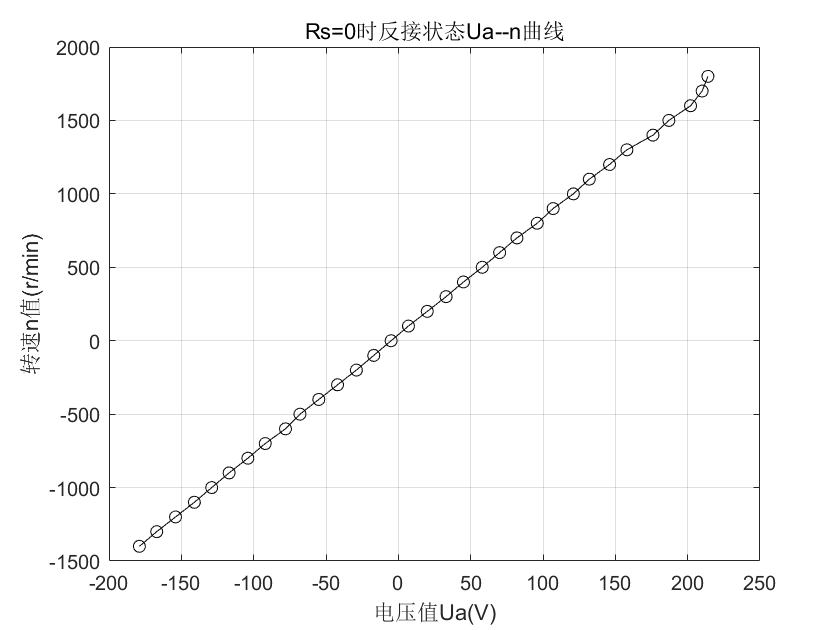

plot(Ua1,n1,'ko-'),grid on;
xlabel('电压值Ua(V)'),ylabel('转速n值(r/min)'),title('Rs=0时反接状态Ua--n曲线')

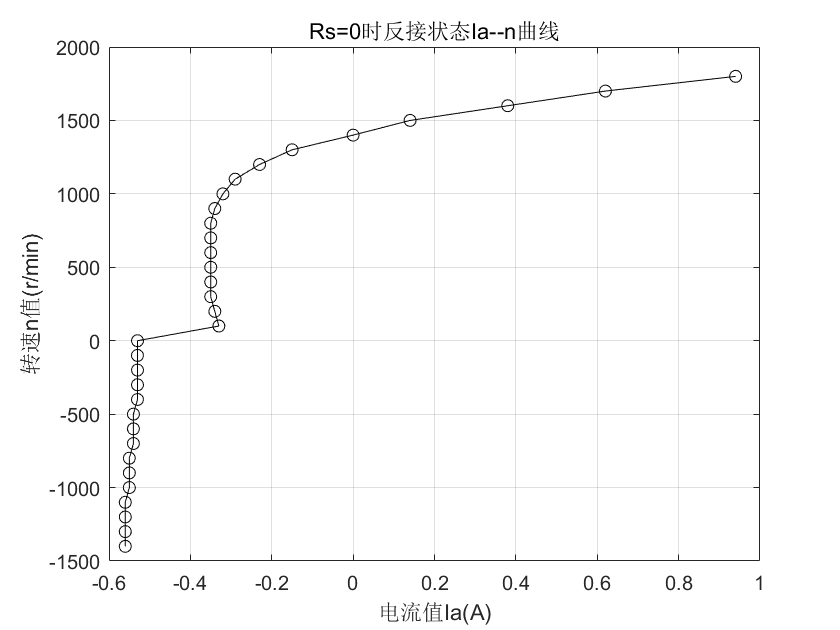

plot(Ia1,n1,'ko-'),grid on;
xlabel('电流值Ia(A)'),ylabel('转速n值(r/min)'),title('Rs=0时反接状态Ia--n曲线')

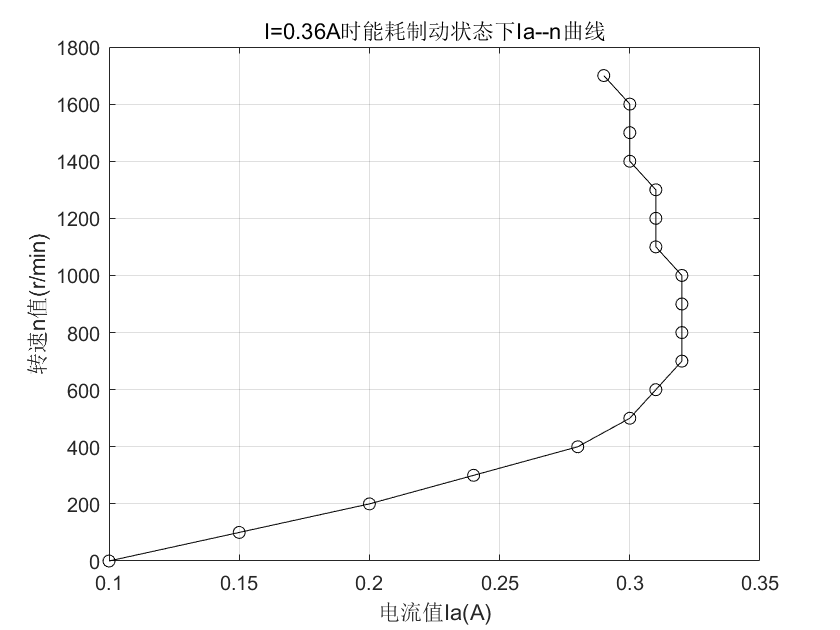

clear
n2 = [1700:-100:0];
Ua1 = [212 201 187 175 165 151 139 128 114 102 90 77 65 52 39 26 14 1];
Ia1 = [0.29 0.30 0.3 0.3 0.31 0.31 0.31 0.32 0.32 0.32 0.32 0.31 0.3 0.28 0.24 0.20 0.15 0.1];

Ua2 = [213 201 190 177 165 154 140 130 116 105 91 79 66 54 41 28 14 1];
Ia2 = [0.57 0.59 0.6 0.62 0.63 0.64 0.66 0.67 0.67 0.68 0.66 0.63 0.59 0.52 0.44 0.32 0.22 0.11];

plot(Ia1,n2,'ko-'),grid on;
xlabel('电流值Ia(A)'),ylabel('转速n值(r/min)'),title('I=0.36A时能耗制动状态下Ia--n曲线')

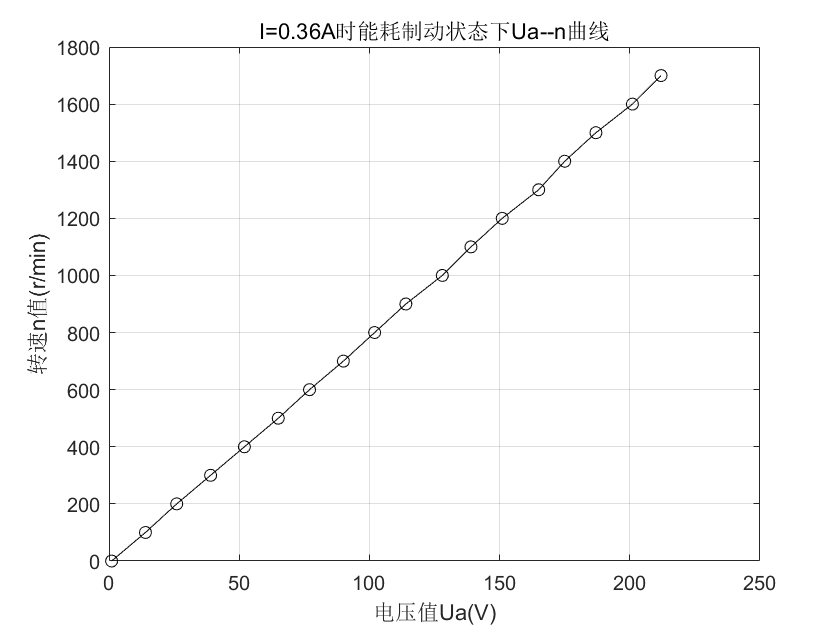

plot(Ua1,n2,'ko-'),grid on;
xlabel('电压值Ua(V)'),ylabel('转速n值(r/min)'),title('I=0.36A时能耗制动状态下Ua--n曲线')

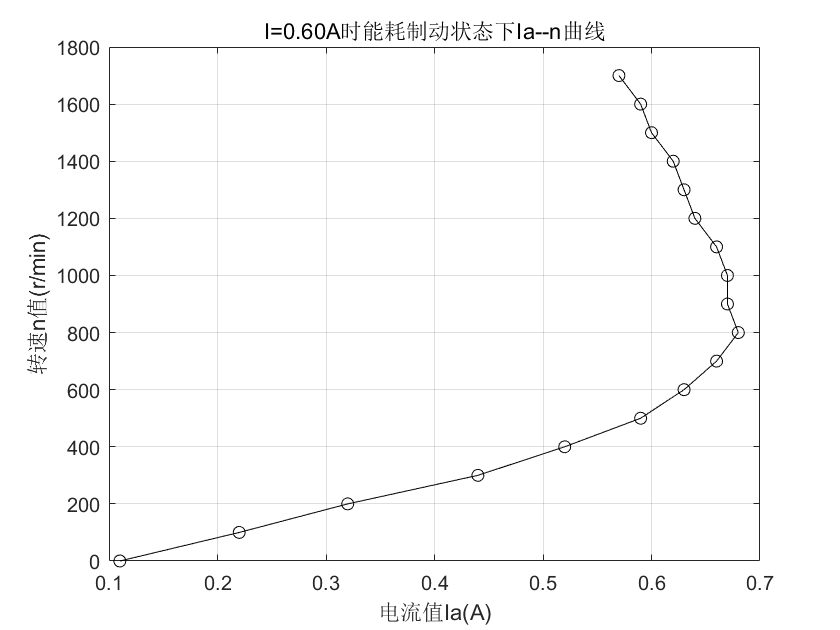


plot(Ia2,n2,'ko-'),grid on;
xlabel('电流值Ia(A)'),ylabel('转速n值(r/min)'),title('I=0.60A时能耗制动状态下Ia--n曲线')

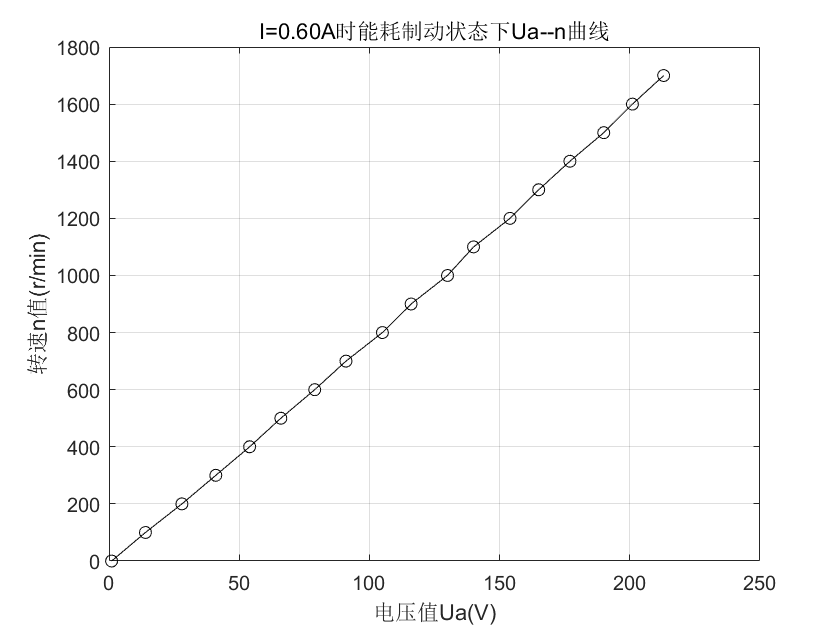

plot(Ua2,n2,'ko-'),grid on;
xlabel('电压值Ua(V)'),ylabel('转速n值(r/min)'),title('I=0.60A时能耗制动状态下Ua--n曲线')